# EE230 HW2 MATLAB Question

*İsmail Enes Bülbül, Abdullah Emir Göğüsdere*

*2442630, 2443075*

## Step b)

p = 0.35

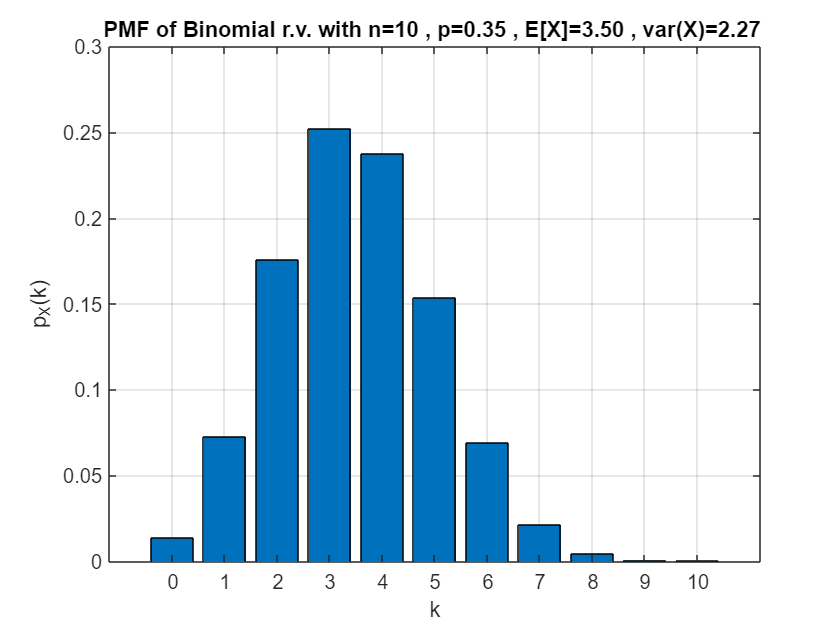

% Determine parameters of Binomial PMF 
p = 0.35 ; n = 10 ; k = 0:10 ; 
% Use pdf() function in Matlab to get PMF values of Binomial PMF at required % points 
pXk = pdf('bino' ,k ,n, p) ; 
% Compute Expected Value 
ExpVal = sum( k .* pXk ) ;
% Compute Variance 
Var = sum( (k-ExpVal) .^2 .* pXk ) ; 
% Plot PDF and label axes
figure , bar(k,pXk); grid ; xlabel('k'); ylabel('p_X(k)') 
% Put a title on plot 
title (sprintf( 'PMF of Binomial r.v. with n=%d , p=%2.2f , E[X]=%3.2f , var(X)=%3.2f ' ,n , p , ExpVal , Var ) ) ;

p = 0.2

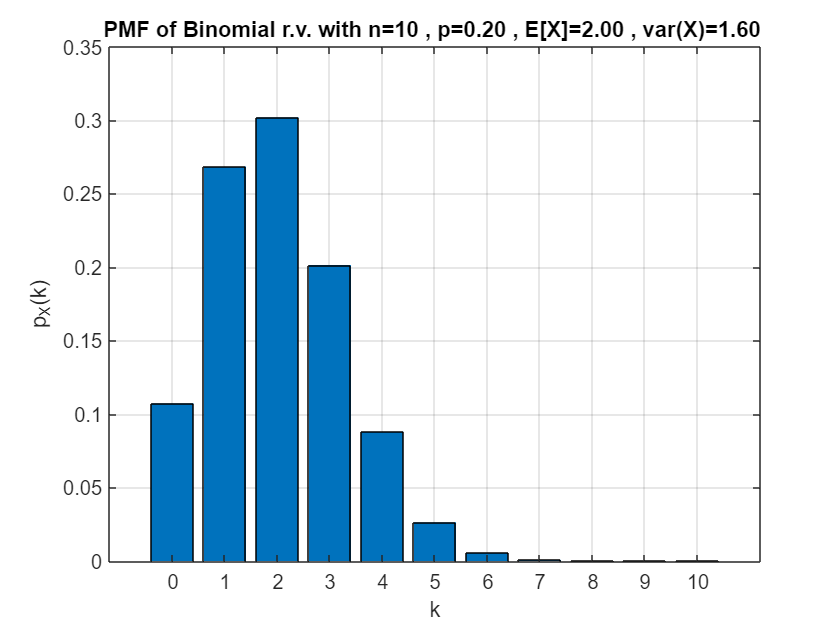

% Determine parameters of Binomial PMF 
p = 0.2 ; n = 10 ; k = 0:10 ; 
% Use pdf() function in Matlab to get PMF values of Binomial PMF at required % points 
pXk = pdf('bino' ,k ,n, p) ; 
% Compute Expected Value 
ExpVal = sum( k .* pXk ) ;
% Compute Variance 
Var = sum( (k-ExpVal) .^2 .* pXk ) ; 
% Plot PDF and label axes
figure , bar(k,pXk); grid ; xlabel('k'); ylabel('p_X(k)') 
% Put a title on plot 
title (sprintf( 'PMF of Binomial r.v. with n=%d , p=%2.2f , E[X]=%3.2f , var(X)=%3.2f ' ,n , p , ExpVal , Var ) ) ;

## Step c)

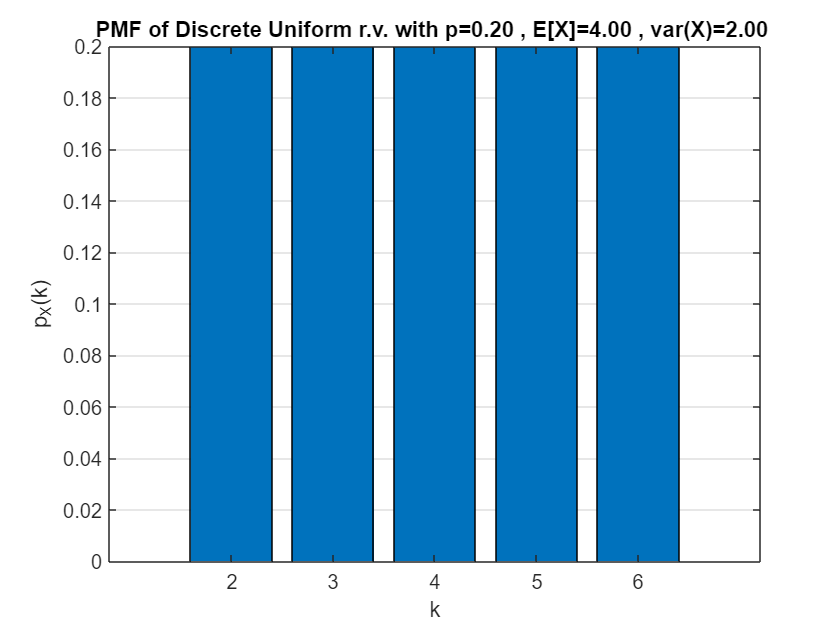

% Determine parameters of Discrete Uniform PMF 
k = 2:6; 
% Use pdf() function in Matlab to get PMF values of Binomial PMF at required % points 
pXk = pdf('Discrete Uniform', k-1, k(end)-1) ; 
% Compute Expected Value 
ExpVal = sum( k .* pXk ) ;
% Compute Variance 
Var = sum( (k-ExpVal) .^2 .* pXk ) ; 
% Plot PDF and label axes
figure , bar(k,pXk); grid ; xlabel('k'); ylabel('p_X(k)') 
% Put a title on plot 
title (sprintf( 'PMF of Discrete Uniform r.v. with p=%2.2f , E[X]=%3.2f , var(X)=%3.2f ' , p , ExpVal , Var ) ) ;

## Step d)

## Step e)

## Step f)

### Step f-i)

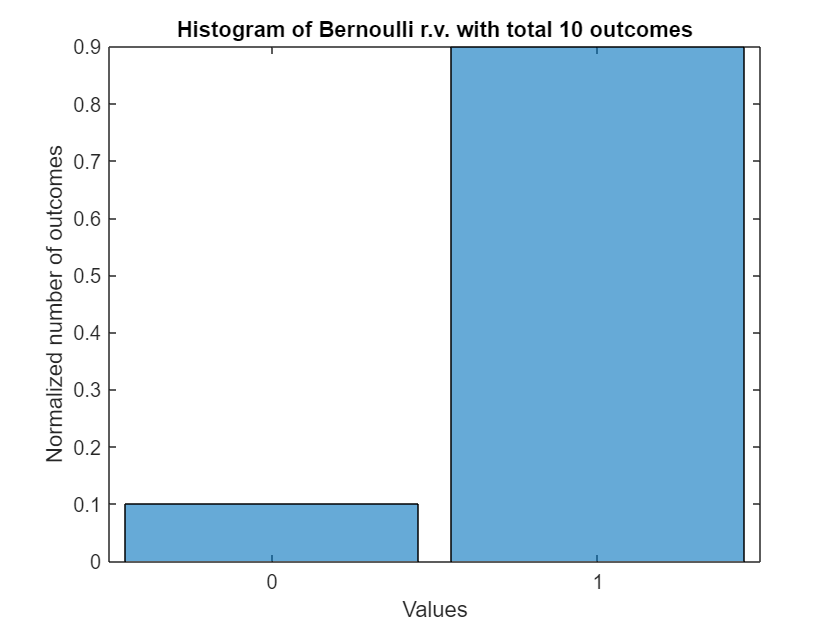

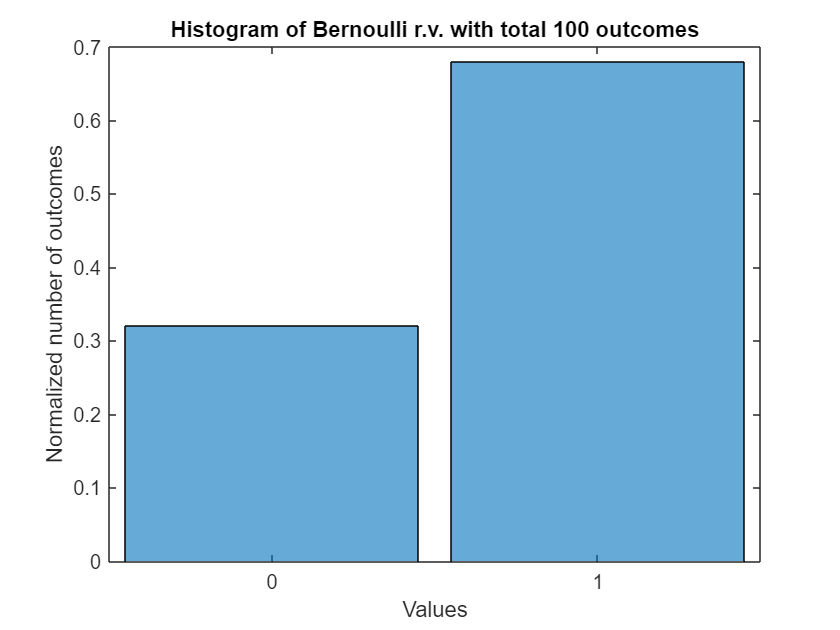

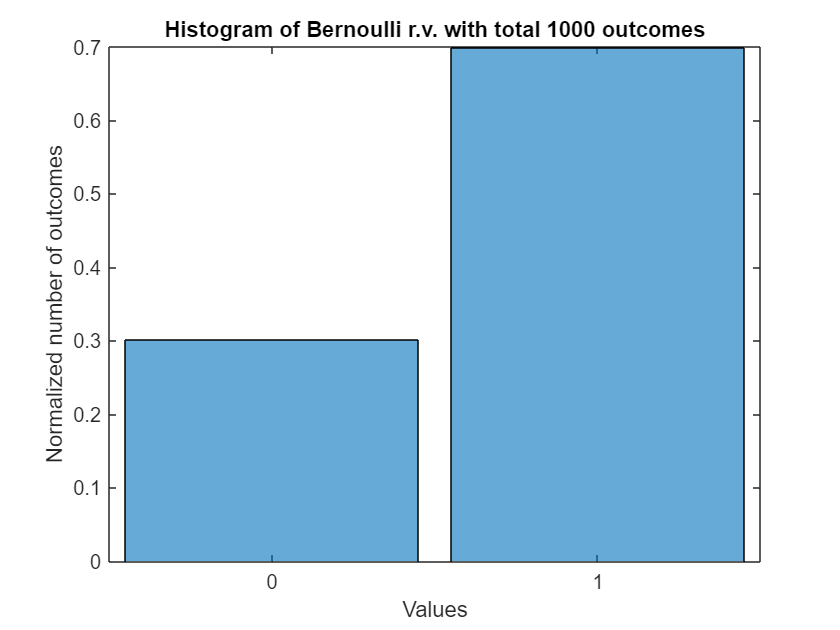

p = 0.7;
numberoftimes = [10 100 1000];
for times = numberoftimes
    plot_bernoulli_histogram(p, times)
end

Bernoulli PMF with pdf() function

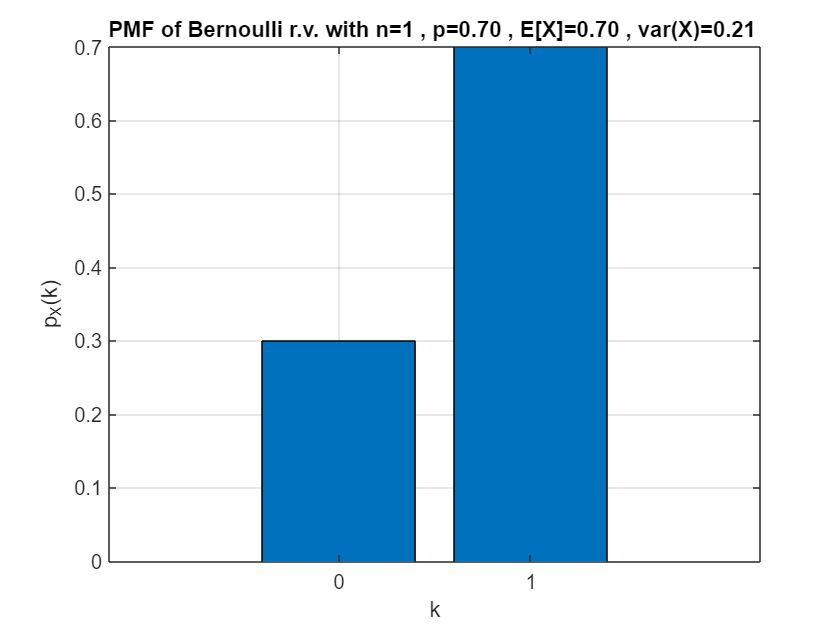

% Determine parameters of Bernoulli PMF 
p = 0.7 ; n = 1 ; k = 0:1;
% Use pdf() function in Matlab to get PMF values of Bernoulli PMF at required % points 
pXk = pdf('bino', k, n, p) ;
% Compute Expected Value 
ExpVal = sum( k .* pXk ) ;
% Compute Variance 
Var = sum( (k-ExpVal) .^2 .* pXk ) ; 
% Plot PDF and label axes
figure , bar(k,pXk); grid ; xlabel('k'); ylabel('p_X(k)') 
% Put a title on plot 
title (sprintf( 'PMF of Bernoulli r.v. with n=%d , p=%2.2f , E[X]=%3.2f , var(X)=%3.2f ' ,n , p , ExpVal , Var ) ) ;

#### Comment:

If we look at the histograms drawn by the plot_bernoulli_histogram(), as the number of total outcomes (numberoftimes) increases, the normalized numbers of outcomes approach (converge) to 0.3 and 0.7 gradually. Therefore, we can state that the histogram with the max total outcome is much more similar to the plot of Bernoulli PMF.

### Step f-ii)

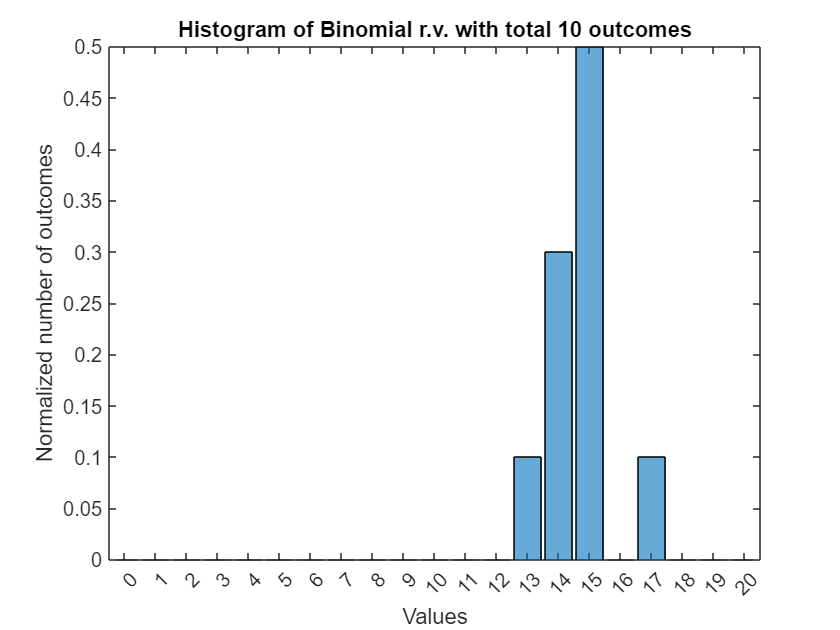

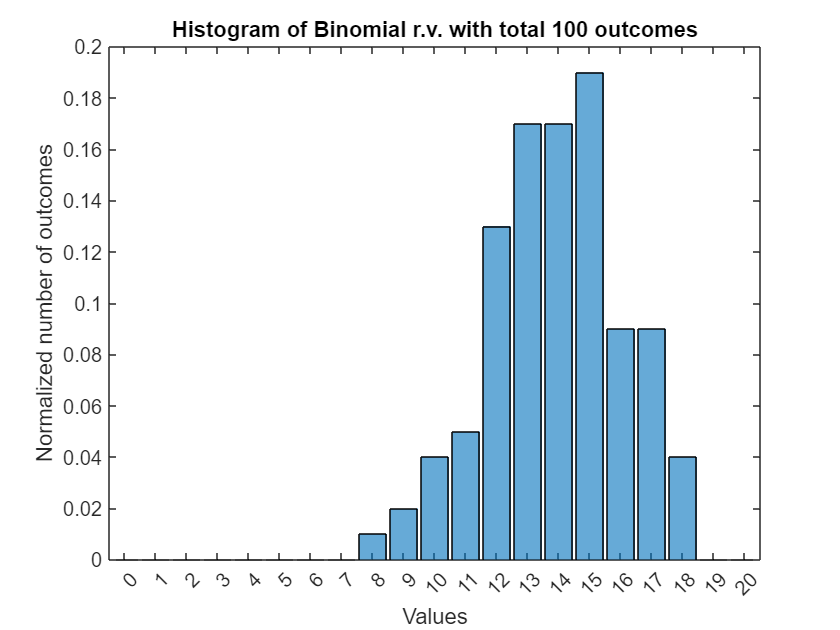

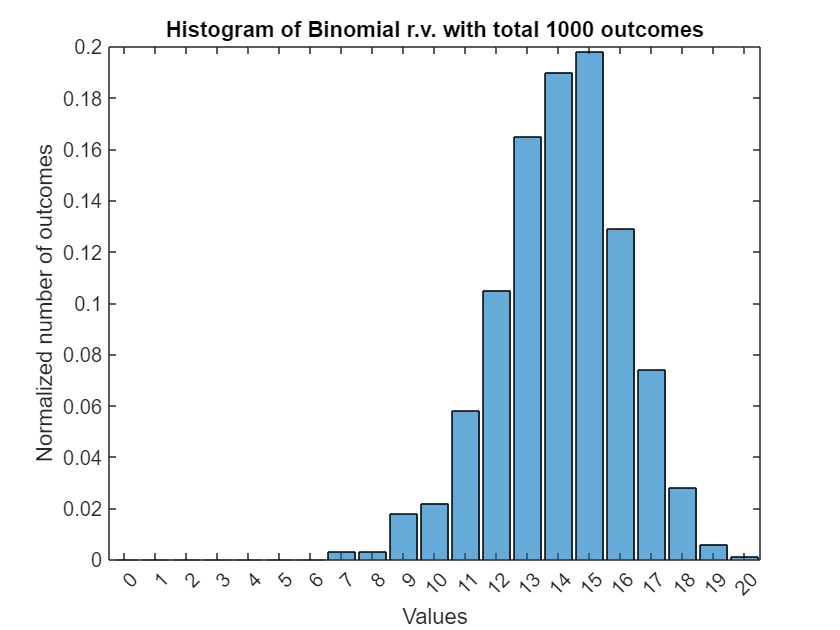

p = 0.7; n = 20;
numberoftimes = [10 100 1000];
for times = numberoftimes
    plot_binomial_histogram(p, n, times)
end

Binomial PMF with pdf() function

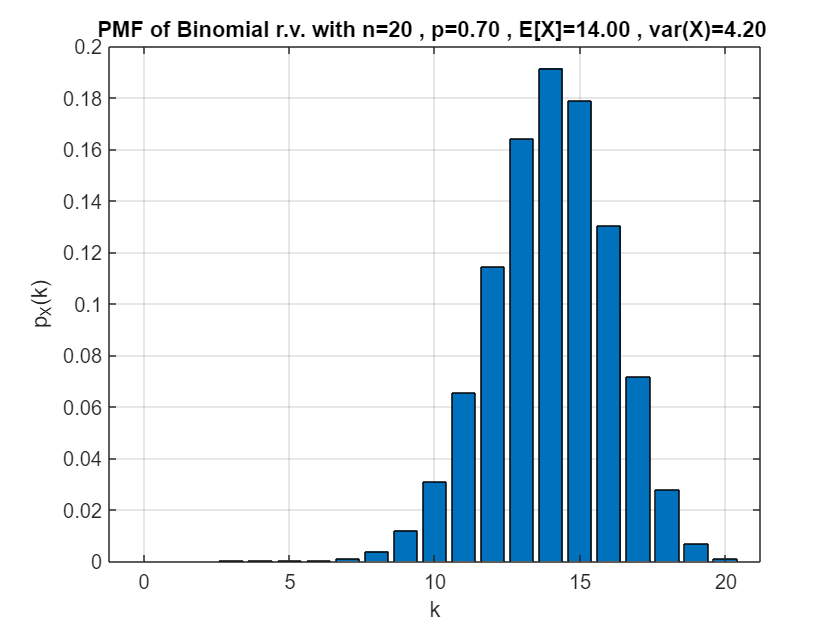

% Determine parameters of Binomial PMF 
p = 0.7 ; n = 20 ; k = 0:n ; 
% Use pdf() function in Matlab to get PMF values of Binomial PMF at required % points 
pXk = pdf('bino', k, n, p) ; 
% Compute Expected Value 
ExpVal = sum( k .* pXk ) ;
% Compute Variance 
Var = sum( (k-ExpVal) .^2 .* pXk ) ; 
% Plot PDF and label axes
figure , bar(k,pXk); grid ; xlabel('k'); ylabel('p_X(k)') 
% Put a title on plot 
title (sprintf( 'PMF of Binomial r.v. with n=%d , p=%2.2f , E[X]=%3.2f , var(X)=%3.2f ' ,n , p , ExpVal , Var ) ) ;

#### Comment:

Similarly, if we look at the histograms sketched by the plot_binomial_histogram(), as the number of total outcomes (numberoftimes) increases, the plot itself becomes much more identical to the plot of Binomial PMF. Hence, it can be understood that the histogram with the max total outcome is the most similar to the plot of Binomial PMF among the other histograms.

## Functions

function ber_rv = get_bernoulli_rv(p)
    if ~((0<=p)&&(p<=1))
        ME = MException('myComponent:inputError', ...
            'Variable p=%.2f is not between 0 and 1.',p);
        throw(ME)
    end
    if rand<=p
      ber_rv=1;
    else
      ber_rv=0;
    end
end

% No need for k parameter
function binom_rv = get_binomial_rv(p, n)
    if ~(0<=n)
        ME = MException('myComponent:inputError', ...
            'Variable n=%d is not equal of bigger than 0.',n);
        throw(ME)
    end
    binom_rv=0;
    if n~=0
        for step = 1:n
            binom_rv = binom_rv + get_bernoulli_rv(p);
        end
    end
end

function plot_bernoulli_histogram(p, numberoftimes)
    samples = zeros(1,numberoftimes);
    for step = 1:numberoftimes
        samples(step) = get_bernoulli_rv(p);
    end
    C = categorical(samples,0:1);
    figure;
    histogram(C,'Normalization','probability')
    xlabel('Values')
    ylabel('Normalized number of outcomes')
    title(sprintf('Histogram of Bernoulli r.v. with total %d outcomes', numberoftimes))
end

function plot_binomial_histogram(p, n, numberoftimes)
    samples = zeros(1,numberoftimes);
    for step = 1:numberoftimes
        samples(step) = get_binomial_rv(p, n);
    end
    C = categorical(samples,0:n);
    figure;
    histogram(C,'Normalization','probability')
    xlabel('Values')
    ylabel('Normalized number of outcomes')
    title(sprintf('Histogram of Binomial r.v. with total %d outcomes', numberoftimes))
end